[mics, fs] = audioread("double_mics.wav");
ref = mics(:, 2);
target = mics(:, 1);

step_sizes = [.0001, .001, .01, .1];
ir_lens = [128, 256, 512, 1024];

N = length(ir_lens);

max_iters = 50;

mses = zeros(N, max_iters);
preds = zeros(N, length(target));
factors = zeros(N, 1);


panel_ir = clipped_irs(128, 2);
best_filt = FxLMS(ref, target, panel_ir, 256, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

step_size = 0.0002;

for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);


    [ref, factor, target, panel_ir] = normalize_data(ref, target, panel_ir);


    filter_order = ir_len * 2;

    
    fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
    fxlms.gpu = false;
    [pred_i, mses_i] = fxlms.learn(max_iters);

    mses(i, :) = mses_i;
    preds(i, :) = denormalize_data(pred_i, factor);
        
    disp(mses_i)

    if mses_i(end) < min_mse
        min_mse = mses_i(end);
        min_i = i;
        
        best_filt = fxlms;
    end
 

    [ref, target, panel_ir] = denormalize_data(ref, factor, target, panel_ir);
    factors(i) = factor;

    disp('');

end

   1.0e-04 *

    0.2137    0.1550    0.1377    0.1291    0.1238    0.1201    0.1172    0.1148    0.1129    0.1113    0.1099    0.1087    0.1076    0.1067    0.1059    0.1052    0.1045    0.1040    0.1034    0.1030    0.1026    0.1022    0.1018    0.1015    0.1012    0.1010    0.1007    0.1005    0.1003    0.1001    0.0999    0.0998    0.0996    0.0995    0.0994    0.0993    0.0992    0.0990    0.0990    0.0989    0.0988    0.0987    0.0986    0.0986    0.0985    0.0985    0.0984    0.0983    0.0983    0.0982

   1.0e-04 *

    0.1936    0.1300    0.1148    0.1072    0.1025    0.0993    0.0969    0.0951    0.0936    0.0923    0.0912    0.0902    0.0894    0.0886    0.0879    0.0873    0.0867    0.0862    0.0857    0.0853    0.0849    0.0845    0.0842    0.0839    0.0836    0.0833    0.0831    0.0828    0.0826    0.0824    0.0822    0.0820    0.0818    0.0817    0.0815    0.0813    0.0812    0.0811    0.0809    0.0808    0.0807    0.0806    0.0805    0.0804    0.0803    0.0802    0.0801

figure
plot(mses(1, :))
hold on
plot(mses(2, :))
hold on
plot(mses(3, :))
hold on
plot(mses(4, :))
% set(gca, 'XScale', 'log')
xlim([1, max_iters])
% xticks(n_iters)

legend("ir=128", "ir=256", "ir=512", "ir=1024")
xlabel("n\_iter")
ylabel("MSE with step size 0.25")
title("MSE vs Iterations")

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, squeeze(preds(min_i, :)));
legend("ground truth", "best prediction")
 

title(sprintf('Prediction from ir_len=%d', ir_lens(min_i)), 'Interpreter', 'None')
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

% figure
% plot(squeeze(mses(min_i, min_j, :)))
% title('MSE from recorded reverb')
% xlabel('Iteration')
% ylabel('MSE')
% legend(sprintf('ir_len=%d, n_iter=%d', ir_lens(min_i), n_iters(min_j)))

min_i % ir_length

min_i = 2

% min_j % step size

N = length(step_sizes);

max_iters = 50;

mses = zeros(N, max_iters);
preds = zeros(N, length(target));
factors = zeros(N, 1);

panel_ir = clipped_irs(128, 2);
best_filt = FxLMS(ref, target, panel_ir, 256, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

ir_len = 256;

for i = 1:N
    step_size = step_sizes(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);


    [ref, factor, target, panel_ir] = normalize_data(ref, target, panel_ir);


    filter_order = ir_len * 2;

    
    fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
    fxlms.gpu = false;
    [pred_i, mses_i] = fxlms.learn(max_iters);

    mses(i, :) = mses_i;
    preds(i, :) = denormalize_data(pred_i, factor);
        
    disp(mses_i)

    if mses_i(end) < min_mse
        min_mse = mses_i(end);
        min_i = i;
        
        best_filt = fxlms;
    end
 

    [ref, target, panel_ir] = denormalize_data(ref, factor, target, panel_ir);
    factors(i) = factor;

    disp('');

end

   1.0e-04 *

    0.2271    0.1562    0.1349    0.1241    0.1172    0.1123    0.1086    0.1057    0.1034    0.1016    0.1000    0.0987    0.0975    0.0965    0.0956    0.0948    0.0940    0.0933    0.0927    0.0921    0.0916    0.0910    0.0906    0.0901    0.0897    0.0893    0.0889    0.0885    0.0882    0.0879    0.0876    0.0873    0.0870    0.0867    0.0864    0.0862    0.0860    0.0857    0.0855    0.0853    0.0851    0.0849    0.0847    0.0846    0.0844    0.0842    0.0841    0.0839    0.0838    0.0836

   1.0e-04 *

    0.1305    0.0936    0.0873    0.0839    0.0818    0.0803    0.0793    0.0785    0.0779    0.0774    0.0770    0.0767    0.0764    0.0762    0.0759    0.0758    0.0756    0.0754    0.0753    0.0752    0.0751    0.0750    0.0749    0.0749    0.0748    0.0747    0.0747    0.0746    0.0746    0.0746    0.0745    0.0745    0.0745    0.0744    0.0744    0.0744    0.0744    0.0744    0.0744    0.0743    0.0743    0.0743    0.0743    0.0743    0.0743    0.0743    0.0743

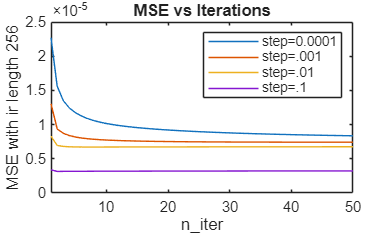

figure
for i = 1:length(step_sizes)
    plot(mses(i, :))
    hold on
end
xlim([1, max_iters])

legend("step=0.0001", "step=.001", "step=.01", "step=.1")
xlabel("n\_iter")
ylabel("MSE with ir length 256")
title("MSE vs Iterations")

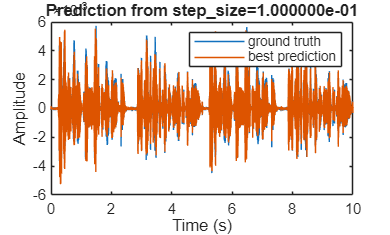

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, squeeze(preds(min_i, :)));
legend("ground truth", "best prediction")
 

title(sprintf('Prediction from step_size=%d', step_sizes(min_i)), 'Interpreter', 'None')
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off